# Average Power - Habituated Vs. Unhabituated in KO and Control

## Summary

The purpose of this script is to find the average power at each frequency for each mouse in the habituated and unhabituated states

Steps:

- Make each trial 1,800,000 samples (= 1,800,000 ms = 30 mins = length of shortest habituated trial)

- Visually analyze data with basic spectrogram and remove artifacts

- Vertically concatenate habituated and unhabituated trials for each mouse

- Use function mtspectrumsegc to take average power over window of 10 seconds and average all together 

- Compare

## Set Parameters for Chronux Spectrogram

% Setting parameters
params.Fs = 1000; %Sampling frequency of input data (1000 = 1000 hz = 1 sample per millisecond)
params.fpass = [0 50]; % Which frequencies to look at [lowest_wanted highest_wanted]
params.pad = 0; % will add 0's to fit into a power of 2 for better calculation (0 is default and adds 0's to the next power of 2)
TW = 5; % the time-bandwidth product 
K = 9; % the number of tapers, K = 2*TW - 1 
params.tapers = [TW K]; 


## Load Datasets into Grouped Conditions

% Load each unhabituated trial for each
controls_unhabituated_unstandardized = {CT2, CT4}

controls_unhabituated_unstandardized = 1×2 cell array
    {3726858×2 single}    {3675772×2 single}


knockouts_unhabituated_unstandardized = {KO2, KO4}

knockouts_unhabituated_unstandardized = 1×2 cell array
    {3689071×2 single}    {3770358×2 single}



% Load each habituated trial for each
controls_habituated_unstandardized={CT1, CT3, CT8}

controls_habituated_unstandardized = 1×3 cell array
    {1893260×2 single}    {3716176×2 single}    {3653016×2 single}


knockouts_habituated_unstandardized= {KO1, KO3, KO8}

knockouts_habituated_unstandardized = 1×3 cell array
    {1890190×2 single}    {3517539×2 single}    {3861380×2 single}


## Standardize Length of Each Dataset

Commented out - not standardizing length for seg-average calculations as I am vertically concatenating all of each condition together

%{
% Standardize the lengths of each array 
desired_length = 1000000

x = 3726858×2 single matrix
   -0.5502    0.9033
   -0.5538    0.8619
   -0.5545    0.9024
   -0.5555    0.8537
   -0.5545    0.8685
   -0.5568    0.9089
   -0.5607    0.9053
   -0.5565    0.9922
   -0.5588    1.0464
   -0.5624    1.0293


x = 7402630×2 single matrix
   -0.5502    0.9033
   -0.5538    0.8619
   -0.5545    0.9024
   -0.5555    0.8537
   -0.5545    0.8685
   -0.5568    0.9089
   -0.5607    0.9053
   -0.5565    0.9922
   -0.5588    1.0464
   -0.5624    1.0293


result = 7402630×2 single matrix
   -0.5502    0.9033
   -0.5538    0.8619
   -0.5545    0.9024
   -0.5555    0.8537
   -0.5545    0.8685
   -0.5568    0.9089
   -0.5607    0.9053
   -0.5565    0.9922
   -0.5588    1.0464
   -0.5624    1.0293


CTL_unhab_cat = 7402630×2 single matrix
   -0.5502    0.9033
   -0.5538    0.8619
   -0.5545    0.9024
   -0.5555    0.8537
   -0.5545    0.8685
   -0.5568    0.9089
   -0.5607    0.9053
   -0.5565    0.9922
   -0.5588    1.0464
   -0.5624    1.0293


x = 3689071×2 single matrix
   -2.3264    0.0218
   -2.3278    0.0116
   -2.3255    0.0313
   -2.3261    0.0379
   -2.3281    0.0366
   -2.3278    0.0221
   -2.3264   -0.0193
   -2.3281   -0.0298
   -2.3268   -0.0614
   -2.3274   -0.0601


x = 7459429×2 single matrix
   -2.3264    0.0218
   -2.3278    0.0116
   -2.3255    0.0313
   -2.3261    0.0379
   -2.3281    0.0366
   -2.3278    0.0221
   -2.3264   -0.0193
   -2.3281   -0.0298
   -2.3268   -0.0614
   -2.3274   -0.0601


result = 7459429×2 single matrix
   -2.3264    0.0218
   -2.3278    0.0116
   -2.3255    0.0313
   -2.3261    0.0379
   -2.3281    0.0366
   -2.3278    0.0221
   -2.3264   -0.0193
   -2.3281   -0.0298
   -2.3268   -0.0614
   -2.3274   -0.0601


KO_unhab_cat = 7459429×2 single matrix
   -2.3264    0.0218
   -2.3278    0.0116
   -2.3255    0.0313
   -2.3261    0.0379
   -2.3281    0.0366
   -2.3278    0.0221
   -2.3264   -0.0193
   -2.3281   -0.0298
   -2.3268   -0.0614
   -2.3274   -0.0601


scontrols_unhab_w60 = standardize_length(controls_unhabituated_unstandardized, desired_length)
sknockouts_unhab_w60 = standardize_length(knockouts_unhabituated_unstandardized, desired_length)

x = 1893260×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


x = 5609436×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


x = 9262452×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


result = 9262452×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


CTL_hab_cat = 9262452×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


x = 1890190×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


x = 5407729×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


x = 9269109×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


result = 9269109×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


KO_hab_cat = 9269109×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693


scontrols_hab_w60 = standardize_length(controls_habituated_unstandardized, desired_length) 
sknockouts_hab_w60 = standardize_length(knockouts_habituated_unstandardized, desired_length)
%}

## Vertically Concatenate Arrays from each Condition

CTL_unhab_cat = vertcat_cell_array(controls_unhabituated_unstandardized)

xarray = 7402630×2 single matrix
   -0.5502    0.9033
   -0.5538    0.8577
   -0.5545    0.8951
   -0.5555    0.8445
   -0.5545    0.8592
   -0.5568    0.9010
   -0.5607    0.9001
   -0.5565    0.9906
   -0.5588    1.0487
   -0.5624    1.0351


result = 7402630×2 single matrix
   -0.5502    0.9033
   -0.5538    0.8577
   -0.5545    0.8951
   -0.5555    0.8445
   -0.5545    0.8592
   -0.5568    0.9010
   -0.5607    0.9001
   -0.5565    0.9906
   -0.5588    1.0487
   -0.5624    1.0351


scontrols_unhab = 7402630×2 single matrix
   -0.5502    0.9033
   -0.5538    0.8577
   -0.5545    0.8951
   -0.5555    0.8445
   -0.5545    0.8592
   -0.5568    0.9010
   -0.5607    0.9001
   -0.5565    0.9906
   -0.5588    1.0487
   -0.5624    1.0351


KO_unhab_cat = vertcat_cell_array(knockouts_unhabituated_unstandardized)

xarray = 7459429×2 single matrix
   -2.3264    0.0218
   -2.3278    0.0115
   -2.3255    0.0312
   -2.3261    0.0377
   -2.3281    0.0363
   -2.3278    0.0218
   -2.3264   -0.0195
   -2.3281   -0.0297
   -2.3268   -0.0609
   -2.3274   -0.0592


result = 7459429×2 single matrix
   -2.3264    0.0218
   -2.3278    0.0115
   -2.3255    0.0312
   -2.3261    0.0377
   -2.3281    0.0363
   -2.3278    0.0218
   -2.3264   -0.0195
   -2.3281   -0.0297
   -2.3268   -0.0609
   -2.3274   -0.0592


sknockouts_unhab = 7459429×2 single matrix
   -2.3264    0.0218
   -2.3278    0.0115
   -2.3255    0.0312
   -2.3261    0.0377
   -2.3281    0.0363
   -2.3278    0.0218
   -2.3264   -0.0195
   -2.3281   -0.0297
   -2.3268   -0.0609
   -2.3274   -0.0592



CTL_hab_cat = vertcat_cell_array(controls_habituated_unstandardized)

xarray = 9262452×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0589
    0.0165   -0.0738
    0.0149   -0.0637
    0.0156   -0.0765
    0.0123    0.0014
    0.0146   -0.0046
    0.0152   -0.0101
    0.0136   -0.0230
    0.0156   -0.0401


result = 9262452×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0589
    0.0165   -0.0738
    0.0149   -0.0637
    0.0156   -0.0765
    0.0123    0.0014
    0.0146   -0.0046
    0.0152   -0.0101
    0.0136   -0.0230
    0.0156   -0.0401


scontrols_hab = 9262452×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0589
    0.0165   -0.0738
    0.0149   -0.0637
    0.0156   -0.0765
    0.0123    0.0014
    0.0146   -0.0046
    0.0152   -0.0101
    0.0136   -0.0230
    0.0156   -0.0401


KO_hab_cat = vertcat_cell_array(knockouts_habituated_unstandardized)

xarray = 9269109×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0757
    0.0024   -0.0451
    0.0054   -0.0556
    0.0034   -0.0407
    0.0037    0.0107
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0679
    0.0027   -0.0697


result = 9269109×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0757
    0.0024   -0.0451
    0.0054   -0.0556
    0.0034   -0.0407
    0.0037    0.0107
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0679
    0.0027   -0.0697


sknockouts_hab = 9269109×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0757
    0.0024   -0.0451
    0.0054   -0.0556
    0.0034   -0.0407
    0.0037    0.0107
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0679
    0.0027   -0.0697


## Filter out 60 Hz Signal from Each

% removing 60 Hz
scontrols_unhab = remove60_nocell(CTL_unhab_cat, params.Fs)

Control Unhabituated


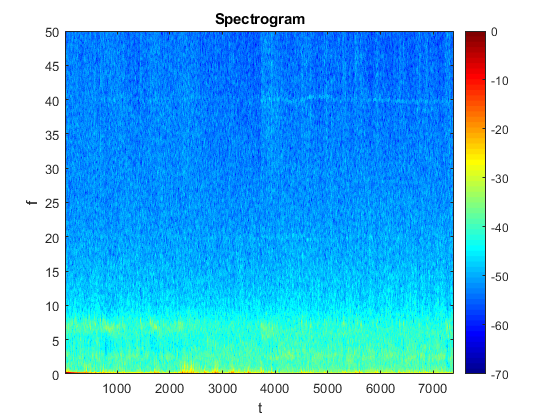

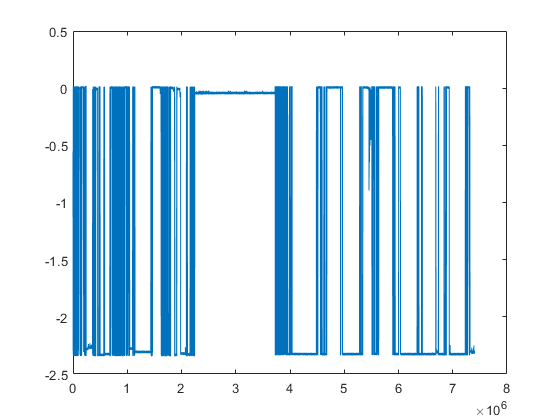

sknockouts_unhab =  remove60_nocell(KO_unhab_cat, params.Fs)

scontrols_hab = remove60_nocell(CTL_hab_cat, params.Fs)
sknockouts_hab = remove60_nocell(KO_hab_cat, params.Fs)


Knockout Unhabituated


## Print out Spectrum for Each 

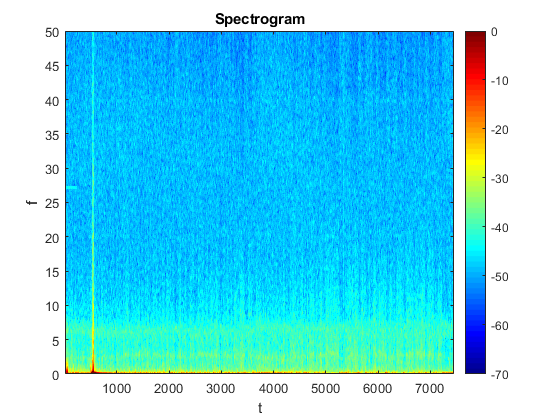

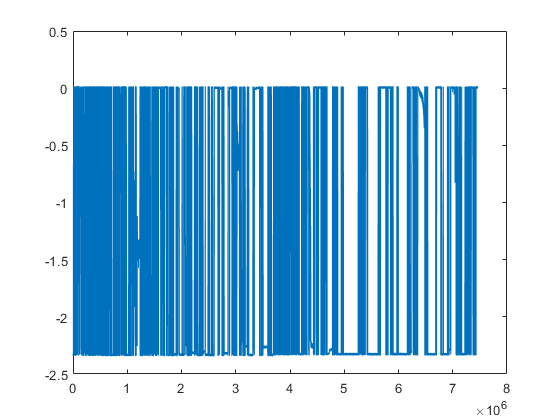

## Print Spectrogram and Running Plot for Each 

disp('Control Unhabituated')

Control Habituated


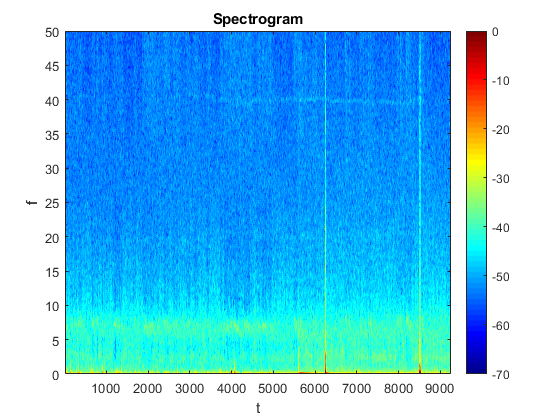

plot_spectrogram(scontrols_unhab, [20 1], params)

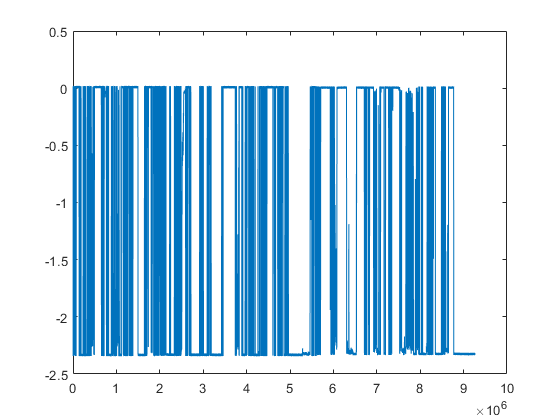

Knockout Habituated


figure; plot (scontrols_unhab(:,1))

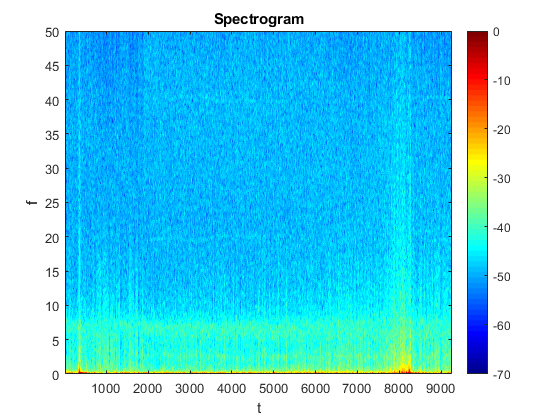

disp('Knockout Unhabituated')

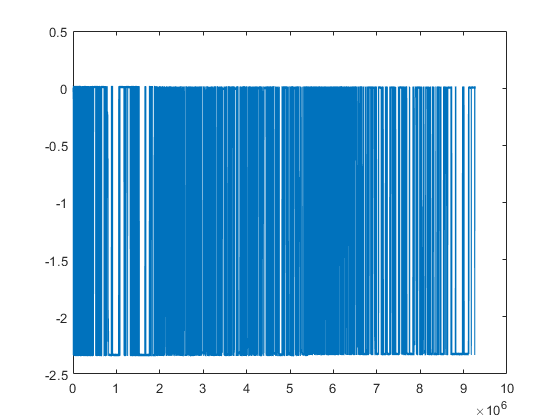

plot_spectrogram(sknockouts_unhab, [20 1], params)

figure; plot(sknockouts_unhab(:,1))

disp('Control Habituated')
plot_spectrogram(scontrols_hab, [20 1], params)
figure; plot(scontrols_hab(:,1))

window = 20


disp('Knockout  Habituated')

Controls Unhabituated


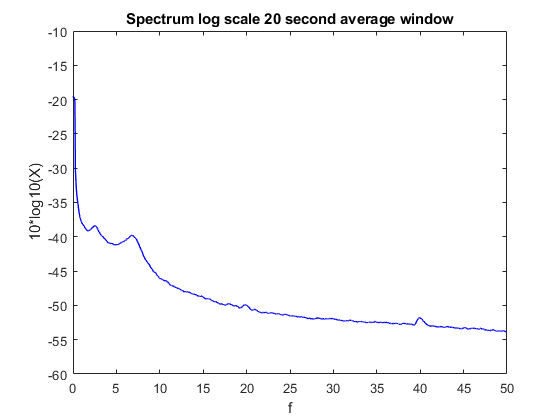

plot_spectrogram(sknockouts_hab, [20 1], params)

figure; plot(sknockouts_hab(:,1))

## Plot Average Seg Spectrum for each (Average window = 20)

Knockout Unhabituated


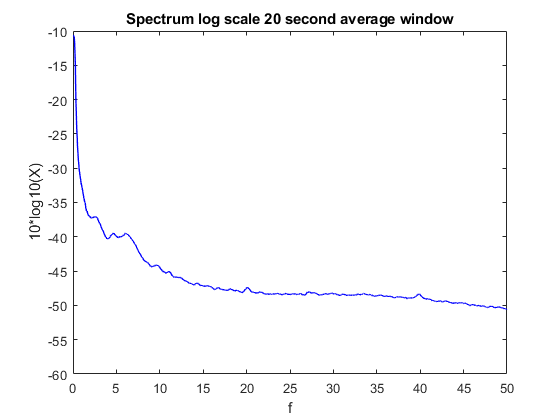

window = 20 % seconds to average over


disp('Controls Unhabituated')

Control Habituated


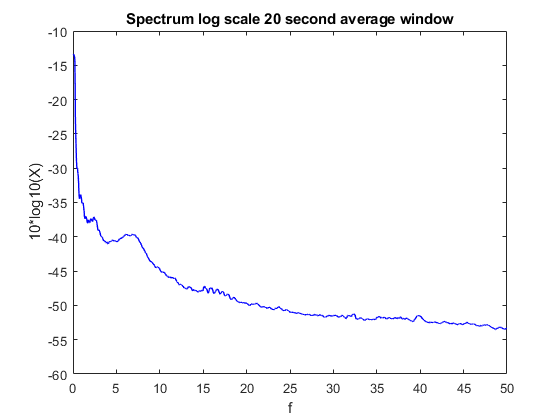

plot_spectrum_seg(scontrols_unhab, window, params)


disp('Knockout Unhabituated')

Knockout Habituated


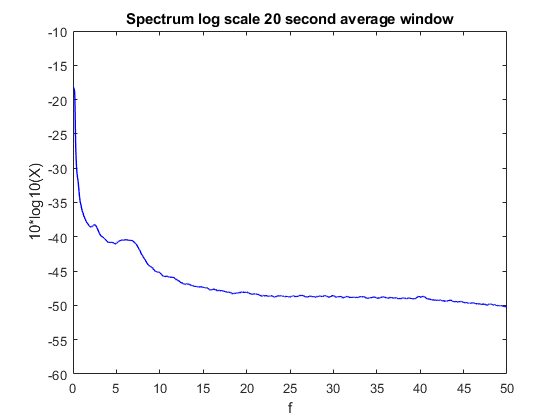

plot_spectrum_seg(sknockouts_unhab, window, params)


disp('Control Habituated')
plot_spectrum_seg(scontrols_hab, window, params)

disp('Knockout Habituated')
plot_spectrum_seg(sknockouts_hab, window, params)




## Scrap


%{
data = LFP(:,2);



 


% Frequency spectrum
[S,f] = mtspectrumc(data,params);


figure; plot_vector(S,f); title('Raw data spectrum log scale');
figure; plot_vector(S,f,'n'); title('Raw data spectrum linear scale')%linear scale

%spectrogeam no average
movingwin = [5 .5]

[S1, t1, f1] = mtspecgramc(data,movingwin,params)
figure; plot_matrix(S1,t1,f1); caxis([-100 0])



win = 10 % length in seconds to average over

segave = 1 
[S,f]=mtspectrumsegc(data,win,params,segave)
figure; plot_vector(S,f); title('Spectrum log scale 10 second average window'); 

%}




%{
% removing 60 Hz
alpha = 0.999; 
omega = 2*pi*60/params.Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];
datano60 = filter(num,den,data);
[S,f] = mtspectrumc(datano60,params);
figure; plot_vector(S,f); title('Spectrum after 60 Hz notch');
%}


# Functions to be used 

## Interatively Run LFP Analysis

function result = run_lfp_analysis(cell_array_standardized)
for ii = 1:length(cell_array_standardized)
    LFP = cell_array_standardized{ii}
    lfp_analysis_CH
end
end


## Standardize Length of Arrays

function result = standardize_length(cell_array, len)
% This function takes a cell array (cell_array) containing a set of arrays
% and makes them all the same length (len) from 1 to len
for ii = 1:length(cell_array)
    cell_array{ii} = cell_array{ii}(1:len,:)
end
result = cell_array
end


## Remove 60Hz Noise from Cell Array of Datasets

function result = remove60(cell_array, Fs)
% This function removes 60 Hz noise from signal

% Set parameters for filter

%%%%global params.Fs

alpha = 0.998; 
omega = 2*pi*60/Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

for ii = 1:length(cell_array)
    cell_array{ii}(:,2) = (filter(num,den,cell_array{ii}(:,2)))
end
result = cell_array
end

## Remove 60Hz Noise from Array

function result = remove60_nocell(xarray, Fs)
% This function removes 60 Hz noise from signal

% Set parameters for filter

%%%%global params.Fs

alpha = 0.9975; 
omega = 2*pi*60/Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

xarray (:,2) = filter(num,den,xarray(:,2))

result = xarray
end

## Calulate and Plot Spectrum over Average Window

function result = plot_spectrum_seg(arrayx, window, params)

% window is length in seconds to average over
segave = 1 ;
[S,f]=mtspectrumsegc(arrayx(:,2),window,params,segave);
figure; plot_vector(S,f); title('Spectrum log scale 20 second average window'); ylim([-60 -10])

end

## Calculate and Plot Spectrogram

function result = plot_spectrogram (arrayx, movingwin, params)

[S2, t2, f2] = mtspecgramc(arrayx(:,2), movingwin,params);
figure; plot_matrix(S2,t2,f2); colorbar; colormap jet; caxis ([-70 0])

end